This works with the Simulink model to perform system identification.  There are a couple of subtleties with the Matlab FFT, but hopefully it's understandable.

sim('System_Identification')
Fs = 1000;            % Sampling frequency
L = length(simout(:,1)); % Length of signal

Now take the FFT of the outputs.  Note that Matlab gives the 2-sided FFT, so we'll have to rearrange...

U = fft(simout(:,1));
Y = fft(simout(:,2));

The frequency response is the ratio of the FFTs.  Then I'll go ahead and warp it to make it single sided.

P2 = Y./U;
P1 = P2(1:L/2+1);
P1(2:end-1) = P1(2:end-1);

Generate the frequency vector and build the FRD model in Matlab.  FRD is the standard non-parametric LTI model in Matlab - it consists of (complex response, frequency) pairs.

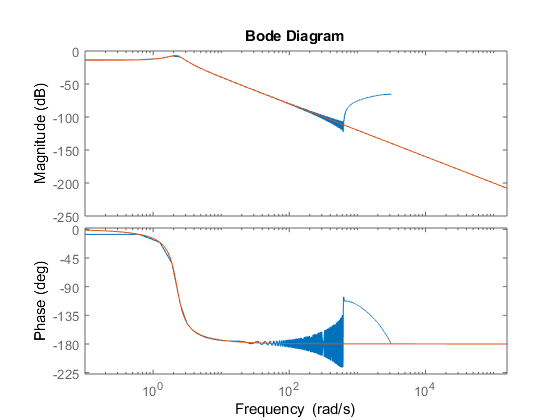

f = Fs*(0:(L/2))/L;
G = frd(P1,f*2*pi);
bode(G,tf(1,[1 1 5]),{0.1,50082*pi})

The response eventually falls apart as the chirp signal shrinks, but we have a good model over much of the range.

Now I'll build a parametric model based on the data.  Start by weighting the low frequency (clean) data heavily.

wt = makeweight(2,30,0.01);

I happen to know that the system is stable, minimum phase, and has relative degree 2.

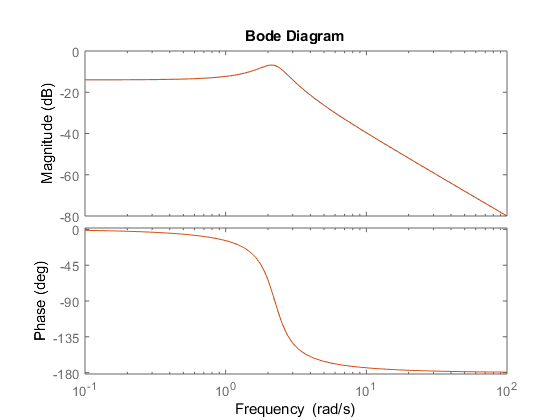

Gmod = fitfrd(G,2,2,wt);
bode(Gmod,tf(1,[1 1 5]))

tf(Gmod)


ans =
 
          0.9934
  ----------------------
  s^2 + 0.9983 s + 4.992
 
Continuous-time transfer function.



Looks like we did pretty well!